img = im2double(imread('flowvis.jpg'));
    [row,col,channels] = size(img) ;
    flow = zeros([row,col,2]) ;    
    origin = [col/2,row/2];
        [X, Y] = meshgrid(1:col, 1:row);


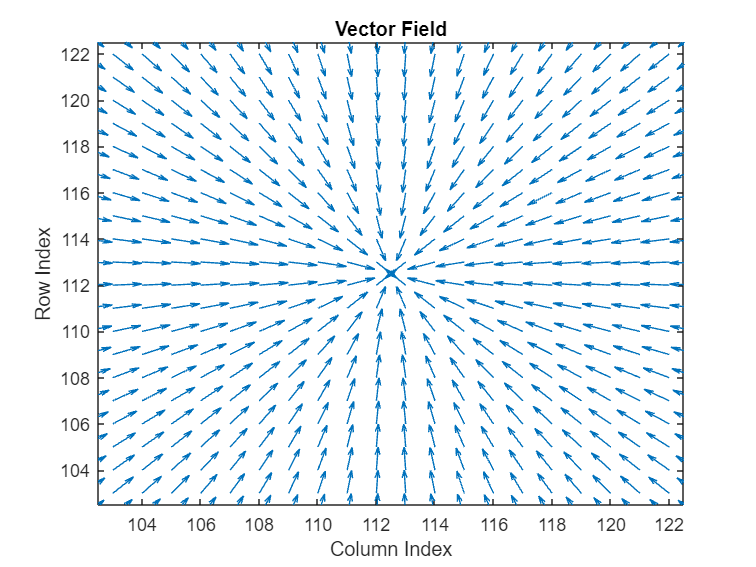

    for i=1:row       
        for j=  1:col
         
            
             vec_2_o = (origin - [j,i] + 0.00000001);
             normalized = vec_2_o/norm(vec_2_o);
             flow(i,j,:) = normalized.';
        end
    end
 quiver(X, Y, flow(:,:,1), flow(:,:,2), 'AutoScale', 'off');
 title('Vector Field');
xlabel('Column Index');
ylabel('Row Index');
xlim([col/2 - 10,col/2 + 10]);
ylim([row/2 - 10,row/2 + 10]);

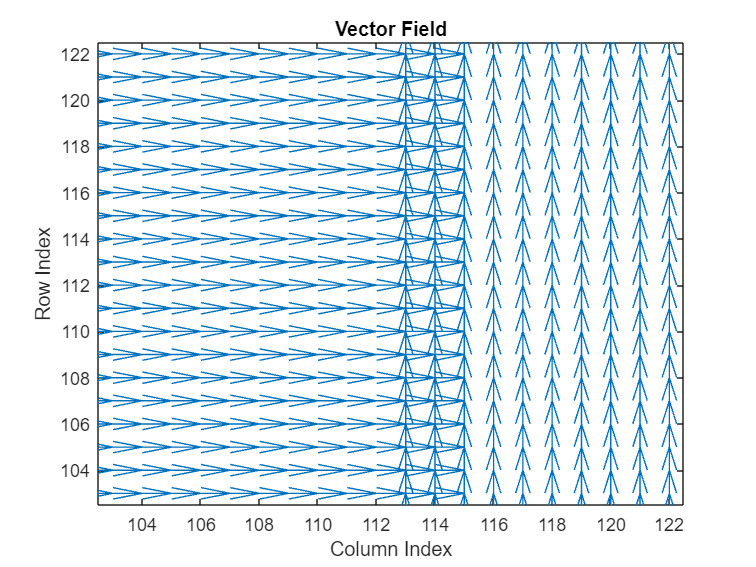

    for i=1:row       
        for j=1:col
            if(j <= col/2)
                flow(i,j,:) = [3;0];
            end
            if(j > col/2)
               flow(i,j,:) = [0;3];
            end
            
            
        end
    end
    im =  quiver(X, Y, flow(:,:,1), flow(:,:,2), 'AutoScale', 'off');
 title('Vector Field');
xlabel('Column Index');
ylabel('Row Index');
xlim([col/2 - 10,col/2 + 10]);
ylim([row/2 - 10,row/2 + 10]);